% ECE 537 Exercise#1
% Group 5
% Muqian Gui - V00870654
% Ruan Hang - V00923058

clc;
clear all;
close all;
% format long g;


% rng(0)
dim = 3; % Setdimension as 3 
K = 1000; % Number of data samples
u1 = [0 ; 4 ; 7]; % Mean for class A
u2 = [10 ; 5 ; 5]; % Mean for class B
u3 = [-2 ; -5 ; -5]; % Mean for class C
% Prescribed covariance matrix for class A
cov_matrix1 = [6.5 2.1651 1.25 ; 2.1651 5.125 2.3816 ; 1.25 2.3816 2.3750];
% Prescribed covariance matrix for class B
cov_matrix2 = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456; -1.4481 -0.6456 1.2880];
% Prescribed covariance matrix for class C
cov_matrix3 = [6.8928 -1.3750 3.1945; -1.3750 3.3572 0.6945; 3.1945 0.6945 3.7500];

data1 = dataGeneratorFunc(dim,K,u1,cov_matrix1); % Data generated for class A
data2 = dataGeneratorFunc(dim,K,u2,cov_matrix2); % Data generated for class A
data3 = dataGeneratorFunc(dim,K,u3,cov_matrix3); % Data generated for class A

% Test the data obtained match the prescribed mean and covariance matrix
muReal_A = mean(data1,1)

muReal_A =      -7.46069872548105e-17                         4                         7


sigmaReal_A = cov(data1)

sigmaReal_A =                        6.5                    2.1651                      1.25
                    2.1651                     5.125                    2.3816
                      1.25                    2.3816                     2.375



muReal_B = mean(data2,1)

muReal_B =     10     5     5


sigmaReal_B = cov(data2)

sigmaReal_B =                     3.0184                    0.4331                   -1.4481
                    0.4331                    0.9436                   -0.6456
                   -1.4481                   -0.6456                     1.288



muReal_C = mean(data3,1)

muReal_C =     -2    -5    -5


sigmaReal_C = cov(data3)

sigmaReal_C =                     6.8928                    -1.375                    3.1945
                    -1.375                    3.3572         0.694499999999999
                    3.1945         0.694499999999999                      3.75



% Samples from this exercise saved as data profile for later using
exercise1Data = [data1 ;data2 ;data3];

% combined = reshape(combined,[3,1000,3])
% choices = randi(3,1000,1);
% for v = 1:1000
%     choice = choices(v);
%     data = zeros(1000,3);
%     data(v) = combined(choice,v);
% end
% data;


When the sample number is less then infinity, the sampling variability will be significant. As the sample size is small, the inherent variability in the samplel will cause the computed covriance matrix deviate from the prescribed covriance matrix. So the sample charateristics will not exactly match the one specified. Since the size of sample increasing, the accuracy of computed covariance matrix will improve but there might still some small difference from the prescribed one.

To correct this issue, as shown in the function defined below. Transform the random normals to remove the random variation from zero mean and identity convariance. Which is done by subtracting the sample mean (data = data-mean(data,1)) and calculate the cholesky decomposition (data = data/chol(cov(data))). Then the desired sample data can be obtained by (data = data*chol(cov_matrix) +u). The function presented the desired results as shown above. 

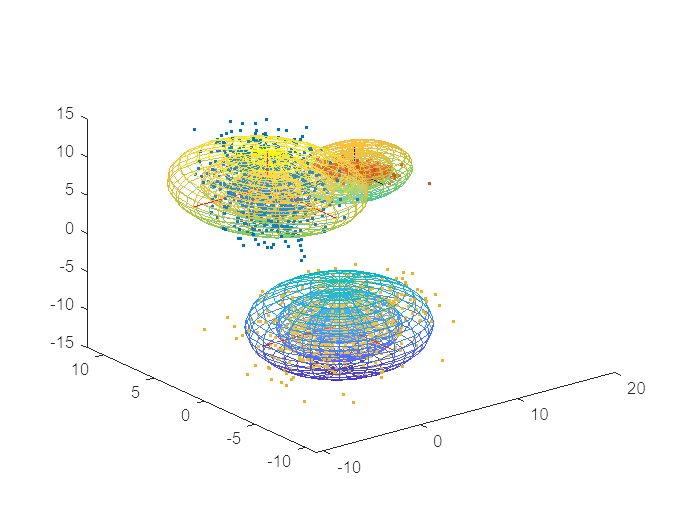

% Plot
% One standard deviation for class A,B,C
s_A = std(data1); 
s_B = std(data2); 
s_C = std(data3); 
[x_A, y_A, z_A] = ellipsoid(0,4,7,s_A(:,1),s_A(:,2),s_A(:,3));
[x_B, y_B, z_B] = ellipsoid(10,5,5,s_B(:,1),s_B(:,2),s_B(:,3));
[x_C, y_C, z_C] = ellipsoid(-2,-5,-5,s_C(:,1),s_C(:,2),s_C(:,3));

% Two standard deviation for class A,B,C
s_2A = 2*std(data1);
s_2B = 2*std(data2); 
s_2C = 2*std(data3); 
[x_2A, y_2A, z_2A] = ellipsoid(0,4,7,s_2A(:,1),s_2A(:,2),s_2A(:,3));
[x_2B, y_2B, z_2B] = ellipsoid(10,5,5,s_2B(:,1),s_2B(:,2),s_2B(:,3));
[x_2C, y_2C, z_2C] = ellipsoid(-2,-5,-5,s_2C(:,1),s_2C(:,2),s_2C(:,3));

% Three standard deviation for class A,B,C
s_3A = 3*std(data1);
s_3B = 3*std(data2);
s_3C = 3*std(data3);
[x_3A, y_3A, z_3A] = ellipsoid(0,4,7,s_3A(:,1),s_3A(:,2),s_3A(:,3));
[x_3B, y_3B, z_3B] = ellipsoid(10,5,5,s_3B(:,1),s_3B(:,2),s_3B(:,3));
[x_3C, y_3C, z_3C] = ellipsoid(-2,-5,-5,s_3C(:,1),s_3C(:,2),s_3C(:,3));

% Principal axes of class A
min_Ax = min(x_3A(:));
xA1 = [0 min_Ax];
yA1 = [4 4];
zA1 = [7 7];
min_Ay = min(y_3A(:));
xA2 = [0 0];
yA2 = [4 min_Ay];
zA2 = [7 7];
max_Az = max(z_3A(:));
xA3 = [0 0];
yA3 = [4 4];
zA3 = [7 max_Az];

% Principal axes of class B
min_Bx = min(x_3B(:));
xB1 = [10 min_Bx];
yB1 = [5 5];
zB1 = [5 5];
min_By = min(y_3B(:));
xB2 = [10 10];
yB2 = [5 min_By];
zB2 = [5 5];
max_Bz = max(z_3B(:));
xB3 = [10 10];
yB3 = [5 5];
zB3 = [5 max_Bz];

% Principal axes of class C
min_Cx = min(x_3C(:));
xC1 = [-2 min_Cx];
yC1 = [-5 -5];
zC1 = [-5 -5];
min_Cy = min(y_3C(:));
xC2 = [-2 -2];
yC2 = [-5 min_Cy];
zC2 = [-5 -5];
min_Cz = min(z_3C(:));
xC3 = [-2 -2];
yC3 = [-5 -5];
zC3 = [-5 min_Cz];

% Plot required graphs on the same figure
plot3(data1(:,1), data1(:,2), data1(:,3),'.')
hold on
mesh(x_A, y_A,z_A,FaceAlpha=0.1)
mesh(x_2A, y_2A,z_2A,FaceAlpha=0.1)
mesh(x_3A, y_3A,z_3A,FaceAlpha=0.1)
line(xA1,yA1,zA1,'Color','red','LineStyle','-')
line(xA2,yA2,zA2,'Color','red','LineStyle','-')
line(xA3,yA3,zA3,'Color','red','LineStyle','-')
plot3(data2(:,1), data2(:,2), data2(:,3),'.')
hold on
mesh(x_B, y_B,z_B,FaceAlpha=0.1)
mesh(x_2B, y_2B,z_2B,FaceAlpha=0.1)
mesh(x_3B, y_3B,z_3B,FaceAlpha=0.1)
line(xB1,yB1,zB1,'Color','black','LineStyle','-')
line(xB2,yB2,zB2,'Color','black','LineStyle','-')
line(xB3,yB3,zB3,'Color','black','LineStyle','-')
plot3(data3(:,1), data3(:,2), data3(:,3),'.')
mesh(x_C, y_C,z_C,FaceAlpha=0.1)
mesh(x_2C, y_2C,z_2C,FaceAlpha=0.1)
mesh(x_3C, y_3C,z_3C,FaceAlpha=0.1)
line(xC1,yC1,zC1,'Color','red','LineStyle','-')
line(xC2,yC2,zC2,'Color','red','LineStyle','-')
line(xC3,yC3,zC3,'Color','red','LineStyle','-')

The larger scale plotting results can be found on the MATLAB Figure profile.

function data = dataGeneratorFunc(dim,K,u,cov_matrix)
    data = randn(K,dim);
    data = data-mean(data,1);
    data = data/chol(cov(data));
    data = data*chol(cov_matrix); 
    data = data+u';
end
